imageDir = fullfile(tempdir, "BraTS");
filename = matlab.internal.examples.downloadSupportFile("vision", "data/sampleBraTSTestSetValid.tar.gz");
untar(filename, imageDir);

imageSubDir = fullfile(imageDir, "sampleBraTSTestSetValid", "imagesTest");
labelSubDir = fullfile(imageDir, "sampleBraTSTestSetValid", "labelsTest");

imageFiles = dir(fullfile(imageSubDir, "*.mat"));
imageSubjects = erase({imageFiles.name}, ".mat");
subjectName = imageSubjects{1};
sliceNumber = 80;

imgData = load(fullfile(imageSubDir, subjectName + ".mat"));
maskData = load(fullfile(labelSubDir, subjectName + ".mat"));

mriSlice = mat2gray(imgData.cropVol(:,:,sliceNumber,1));
mask     = maskData.cropLabel(:,:,sliceNumber);

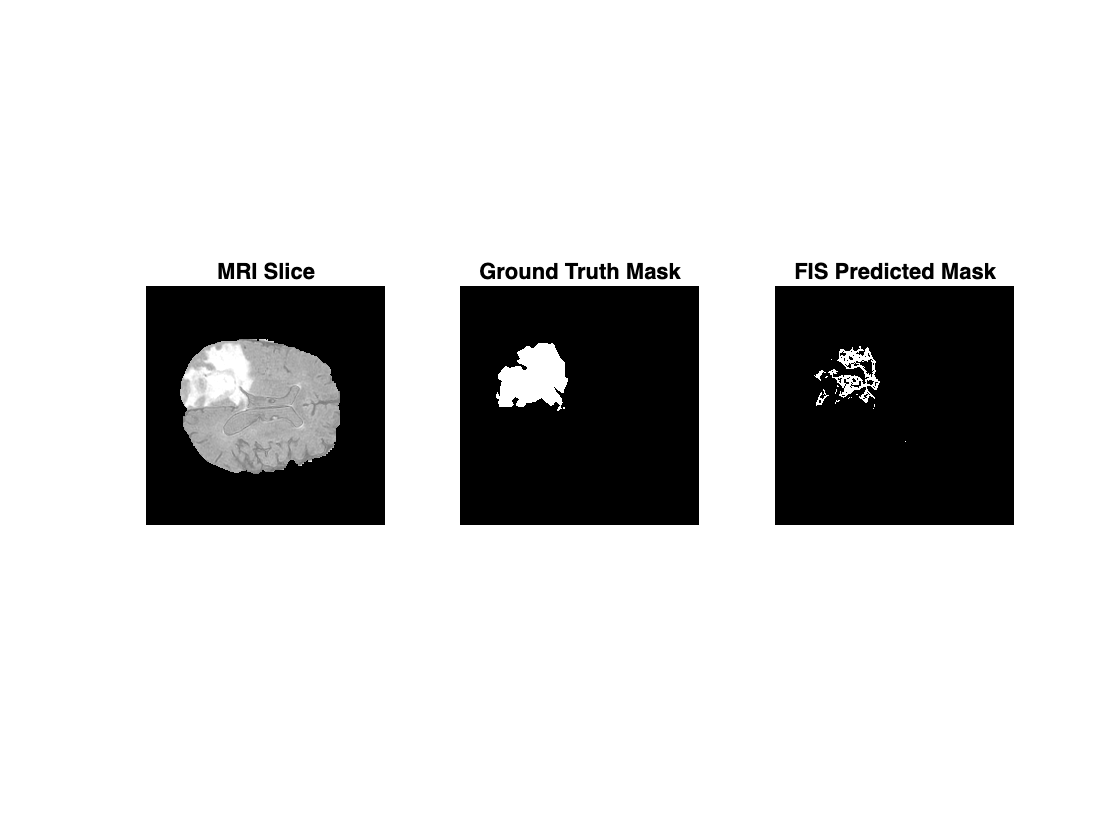

[X, y, coordMap] = extractFeaturesB(mriSlice, mask, 5);

fis = readfis("TumorSegmentation.fis");

[tumorScore, tumorMask] = fisSegmentation(fis, X, coordMap, size(mriSlice));

figure;
subplot(1, 3, 1); imshow(mriSlice, []); title('MRI Slice');
subplot(1, 3, 2); imshow(mask, []); title('Ground Truth Mask');
subplot(1, 3, 3); imshow(tumorMask, []); title('FIS Predicted Mask');


[dice, iou] = evaluateSegmentation(tumorMask, mask);
fprintf("Dice: %.2f%%\n", dice * 100);

Dice: 52.57%


fprintf("IoU: %.2f%%\n", iou * 100);

IoU: 35.65%


% FEATURE SELECTION

save('features_for_GA.mat', 'X', 'y', 'coordMap', 'mask');

opts = optimoptions('ga', ...
    'Display', 'iter', ...
    'PopulationType', 'bitstring', ...
    'PopulationSize', 30, ...
    'MaxGenerations', 10, ...
    'UseParallel', false);

fprintf('\nRunning Genetic Algorithm for Feature Selection...\n');


Running Genetic Algorithm for Feature Selection...


[bestMask, bestFitness] = ga(@evaluateFeatureSubset, 8, [], [], [], [], [], [], [], opts);


Single objective optimization:
8 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1               60           0.445          0.8407        0
    2               88           0.442          0.7667        0
    3              116           0.442          0.6939        1
    4              144           0.442           0.638        2
    5              172           0.442           0.522        3
    6              200           0.442          0.4827        4
    7              228           0.442          0.4823        5
    8              256           0.442          0.4437        6
    9              284           0.442          0.4426        7
   10              312           0.442          0.4798        8
ga stopped because

bestDice = 1 - bestFitness;
fprintf('Best feature subset: %s\n', mat2str(logical(bestMask)));

Best feature subset: [true true false true false true true true]


fprintf('Best Dice score (feature selection only): %.2f%%\n', bestDice * 100);

Best Dice score (feature selection only): 55.80%



X_best = zeros(size(X));  
for k = 1:8
    if bestMask(k)
        X_best(:,k) = X(:,k);
    end
end

% RULE WEIGHT OPTIMIZATION

fprintf('\nRunning Genetic Algorithm for Rule Weight Optimization...\n');


Running Genetic Algorithm for Rule Weight Optimization...


fis = readfis("TumorSegmentation.fis");
numRules = length(fis.Rules);
lb = 0.1 * ones(1, numRules);
ub = ones(1, numRules);

fitnessFunc = @(w) evaluateRuleWeights(w, fis, X_best, coordMap, mask);
optsWeights = optimoptions('ga', ...
    'Display', 'iter', ...
    'PopulationSize', 10, ...
    'MaxGenerations', 5, ...
    'UseParallel', false);

[bestWeights, ~] = ga(fitnessFunc, numRules, [], [], [], [], lb, ub, [], optsWeights);


Single objective optimization:
11 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1               20         0.09216          0.4665        0
    2               29         0.07041          0.3297        0
    3               38         0.07041          0.1906        1
    4               47         0.07041          0.2054        2
    5               56         0.07041          0.1493        3
ga stopped because it exceeded options.MaxGenerations.



optimizedFIS = fis;
for i = 1:numRules
    optimizedFIS.Rules(i).Weight = bestWeights(i);
end

writeFIS(optimizedFIS, "TumorSegmentation_Optimized.fis");

% FINAL RESULTS

[tumorScore, tumorMask]     = fisSegmentation(fis, X_best, coordMap, size(mask));
[tumorScoreOpt, tumorMaskOpt] = fisSegmentation(optimizedFIS, X_best, coordMap, size(mask));

[dice1, iou1] = evaluateSegmentation(tumorMask, mask);
[dice2, iou2] = evaluateSegmentation(tumorMaskOpt, mask);

fprintf('\n--- Final Evaluation Results ---\n');


--- Final Evaluation Results ---


fprintf('Original FIS with selected features:\n  Dice = %.2f%% | IoU = %.2f%%\n', dice1*100, iou1*100);

Original FIS with selected features:
  Dice = 55.80% | IoU = 38.69%


fprintf('Optimized FIS with selected features:\n  Dice = %.2f%% | IoU = %.2f%%\n', dice2*100, iou2*100);

Optimized FIS with selected features:
  Dice = 92.96% | IoU = 86.84%


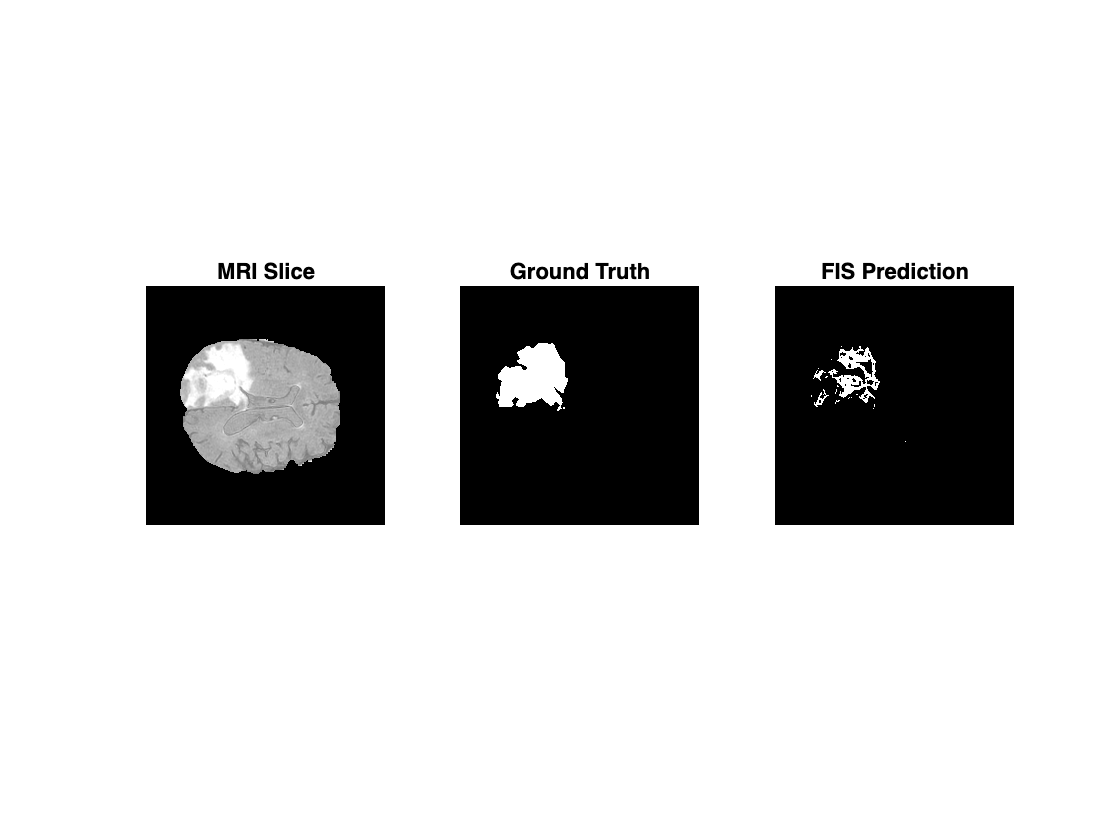


figure;
subplot(1,3,1); imshow(mriSlice, []); title('MRI Slice');
subplot(1,3,2); imshow(mask, []); title('Ground Truth');
subplot(1,3,3); imshow(tumorMask, []); title('FIS Prediction');

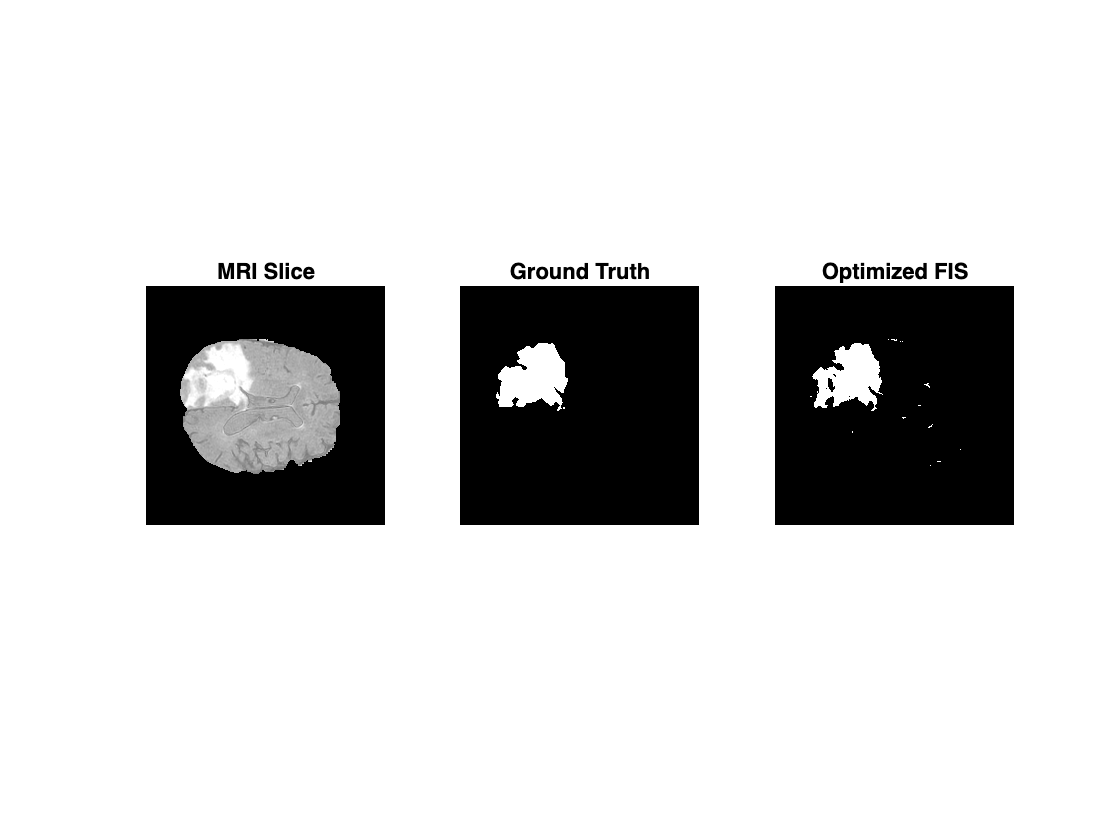


figure;
subplot(1,3,1); imshow(mriSlice, []); title('MRI Slice');
subplot(1,3,2); imshow(mask, []); title('Ground Truth');
subplot(1,3,3); imshow(tumorMaskOpt, []); title('Optimized FIS');